# ESAME___05/06/2026

clear; close all; clc;

## DEFINITIONS

#### Symbolic Variables 

syms x1 x2 x3 x4 dx1 dx2 dx3 dx4 u1 u2 w v real

#### Input-State-Output

% Input
u = [u1;
     u2];

% State
x = [x1;
     x2;
     x3;
     x4];

% Output
y = [x1;
     x3];

#### Dynamic Mode

eq1_sym = dx1 == x2;
eq2_sym = dx2 == -sin(x1) - 0.4*x2 + u1;
eq3_sym = dx3 == x4;
eq4_sym = dx4 == -0.5*sin(x3) - 0.3*x4 + u2 + 0.2*cos(x1);

eqs = [eq1_sym;
       eq2_sym;
       eq3_sym;
       eq4_sym];

sol = solve(eqs, [dx1, dx2, dx3, dx4], "ReturnConditions",true);

% dx/dt
f = [sol.dx1;
     sol.dx2;
     sol.dx3;
     sol.dx4];

% y
g = y;

## LINEARIZATION

A_sym = jacobian(f,x);
B_sym = jacobian(f,u);
C_sym = jacobian(g,x);
D_sym = jacobian(g,u);

% Equilibrium Point
x_star = [0;
          0;
          0;
          0];

u_star = [0;
          -0.2];

A = double(subs(A_sym, [x;u], [x_star; u_star]));
B = double(subs(B_sym, [x;u], [x_star; u_star]));
C = double(subs(C_sym, [x;u], [x_star; u_star]));
D = double(subs(D_sym, [x;u], [x_star; u_star]));

n = size(A,1);
m = size(B,2);

sys = ss(A, B, C, D)


sys =
 
  A = 
         x1    x2    x3    x4
   x1     0     1     0     0
   x2    -1  -0.4     0     0
   x3     0     0     0     1
   x4     0     0  -0.5  -0.3
 
  B = 
       u1  u2
   x1   0   0
   x2   1   0
   x3   0   0
   x4   0   1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


#### Stability

% Calculation and Printing of Eigenvalues
eigenvalues = eig(A);

% Local Stability Analysis (Continuous-Time System)
real_part = real(eigenvalues);

if all(real_part < 0)
    disp('The system is LOCALLY ASYMPTOTICALLY STABLE at x*'); disp('Eigenvalues of the Jacobian matrix A at x*:'); disp(eigenvalues);
    
elseif any(real_part > 0)
    disp('The system is UNSTABLE at x*'); disp('Eigenvalues of the Jacobian matrix A at x*:'); disp(eigenvalues);
    
else
    % Case with max(real_part) == 0
    disp('Critical case (eigenvalues with zero real part). Linear analysis via the eigenvalue approach is INCONCLUSIVE at x*.'); disp('Eigenvalues of the Jacobian matrix A at x*:'); disp(eigenvalues);
end

Il sistema è LOCALMENTE ASINTOTICAMENTE STABILE in x*
Autovalori della matrice Jacobiana A in x*:
  -0.2000 + 0.9798i
  -0.2000 - 0.9798i
  -0.1500 + 0.6910i
  -0.1500 - 0.6910i



#### **Controllability**

if rank(ctrb(A,B)) == n
    disp('The system is completely controllable');
else
    disp('The system is NOT completely controllable');
end

IL sistema è completamente Controllabile


#### Observability

if rank(obsv(A,C)) == n
    disp('The system is completely observable');
else
    disp('The system is NOT completely observable');
end

IL sistema è completamente Osservabile


## EIGENVALUE ASSIGNMENT VIA SYLVESTER'S METHOD

#### Specifications

% Desired eigenvalues
eig_des = [-2 -3 -4 -5];

% Initial state
x0_EIG = [0.15;
          0;
          0.10;
          0];

Lambda = diag(eig_des)

Lambda =     -2     0     0     0
     0    -3     0     0
     0     0    -4     0
     0     0     0    -5


#### Synthesis

% Matrix G with random elements
G = rand(2,4);

X = sylvester(A, -Lambda, -B*G);
K_EIG = G/X

K_EIG =    -3.5345   -4.6983   -3.6863   -1.1490
   10.3713    2.6539  -17.5324   -8.6017


#### Verification

eig_cl = eig(A+B*K_EIG);

disp(eig(A)); disp(eig_cl);

  -0.2000 + 0.9798i
  -0.2000 - 0.9798i
  -0.1500 + 0.6910i
  -0.1500 - 0.6910i

   -2.0000
   -3.0000
   -5.0000
   -4.0000



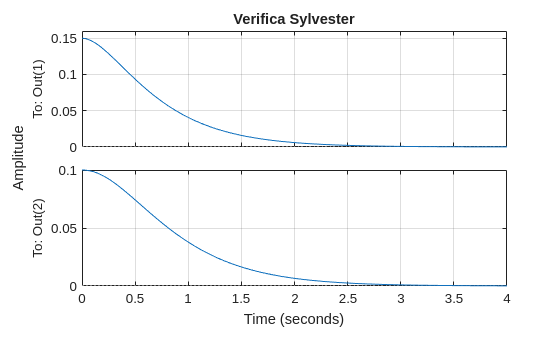

sys_sylvester = ss((A+B*K_EIG), B, C, D);
figure;
initial(sys_sylvester, x0_EIG);
grid on;
title('Sylvester Verification');

## LQR CONTROLLER WITH INTEGRAL ACTION

#### Specifications

% Settling time
Ts = 2;

% Initial condition
x0_LQR = [0.15;
          0;
          0.15;
          0];

% Reference
r_lqr = [0.2;
         0.1];

#### Augumented System

C_LQR = [1, 0, 0, 0;
         0, 0, 1, 0];

A_aug = [A, zeros(n, 2);
         -C_LQR, zeros(2,2)];
eig(A_aug)

ans =    0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.1500 + 0.6910i
  -0.1500 - 0.6910i
  -0.2000 + 0.9798i
  -0.2000 - 0.9798i


n_a = size(A_aug,1);

B_aug = [B;
         zeros(2,2)];
  
C_aug = [eye(n) zeros(n,2)]

C_aug =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0


D_aug = [D;
         zeros(2, 2)]; 

alpha = 4/Ts;

% Spectrum shift to satisfy the settling time specification
A_hat = A_aug - alpha * eye(n_a);
eig(A_hat)

ans =   -2.0000 + 0.0000i
  -2.0000 + 0.0000i
  -2.1500 + 0.6910i
  -2.1500 - 0.6910i
  -2.2000 + 0.9798i
  -2.2000 - 0.9798i


sys_aug = ss(A_aug, B_aug, C_aug, D_aug)


sys_aug =
 
  A = 
         x1    x2    x3    x4    x5    x6
   x1     0     1     0     0     0     0
   x2    -1  -0.4     0     0     0     0
   x3     0     0     0     1     0     0
   x4     0     0  -0.5  -0.3     0     0
   x5    -1     0     0     0     0     0
   x6     0     0    -1     0     0     0
 
  B = 
       u1  u2
   x1   0   0
   x2   1   0
   x3   0   0
   x4   0   1
   x5   0   0
   x6   0   0
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
   y3   0   0   1   0   0   0
   y4   0   0   0   1   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
   y4   0   0
 
Continuous-time state-space model.


#### LQR Synthesis

Q_bar = 1;
Q = C_aug'*Q_bar*C_aug + blkdiag(zeros(n,n), 15*eye(2))

Q =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0    15     0
     0     0     0     0     0    15


R = eye(m);       

% Computation of the LQR gain on the shifted matrix A_hat
K_LQR = lqr(A_hat, B_aug, Q, R);

K_LQR_x = K_LQR(:, 1:n)

K_LQR_x =     0.1225    0.2467    0.0000    0.0000
   -0.0000   -0.0000    0.1572    0.2699


K_LQR_i = K_LQR(:, n+1:end)

K_LQR_i =    -0.1898   -0.0000
    0.0000   -0.1975


#### Simulation verification

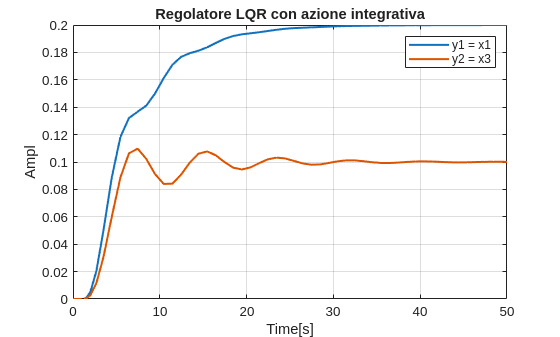

% MATLAB plot
out = sim('Verifica_LQR_05062026.slx');
y1 = out.y1.Data;
y2 = out.y2.Data;
time = out.y1.Time;

figure
plot(time, y1, "LineWidth", 1.5);
grid on
hold on
plot(time, y2, "LineWidth", 1.5);
xlabel("Time[s]");
ylabel("Ampl");
legend('y1 = x1', 'y2 = x3');
title('LQR controller with integral action');

**The Simulink model can be accessed from the following link**

Simulink model:  [Verifica_LQR](matlab:open_system('Verifica_LQR_05062026.slx'))

## **LQG REGULATOR**

#### Specifications

G = eye(4);

W = 0.01*eye(4);

V = 0.001*eye(2);

#### Synthesis

[P_kalman,~,~] = care(A', C', W, V);

% Kalman Gain
L_kalman = P_kalman*C'/V

L_kalman =     3.5063   -0.0000
    1.1471   -0.0000
   -0.0000    3.6709
   -0.0000    1.7379


A_kalman = A-L_kalman*C;
B_kalman = [B, L_kalman];
C_kalman = eye(n);
D_kalman = zeros(n,4);

sys_kalman = ss(A_kalman, B_kalman, C_kalman, D_kalman)


sys_kalman =
 
  A = 
              x1         x2         x3         x4
   x1     -3.506          1   1.14e-16          0
   x2     -2.147       -0.4  5.059e-16          0
   x3   1.14e-16          0     -3.671          1
   x4  2.392e-16          0     -2.238       -0.3
 
  B = 
               u1          u2          u3          u4
   x1           0           0       3.506   -1.14e-16
   x2           1           0       1.147  -5.059e-16
   x3           0           0   -1.14e-16       3.671
   x4           0           1  -2.392e-16       1.738
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1  u2  u3  u4
   y1   0   0   0   0
   y2   0   0   0   0
   y3   0   0   0   0
   y4   0   0   0   0
 
Continuous-time state-space model.


eig(A_kalman)

ans =    -2.4681
   -1.4382
   -1.2090
   -2.7619


#### Simulation verification

Simulink model:  [Verifica_LQG](matlab:open_system('Verifica_LQG_05062026.slx'))

## **SVD COMPRESSION**

#### Image reading and grayscale conversion

I_orig = imread('Image_05062026.jpg');
I_gray = rgb2gray(I_orig);
I = double(I_gray); 

#### Original grayscale image   

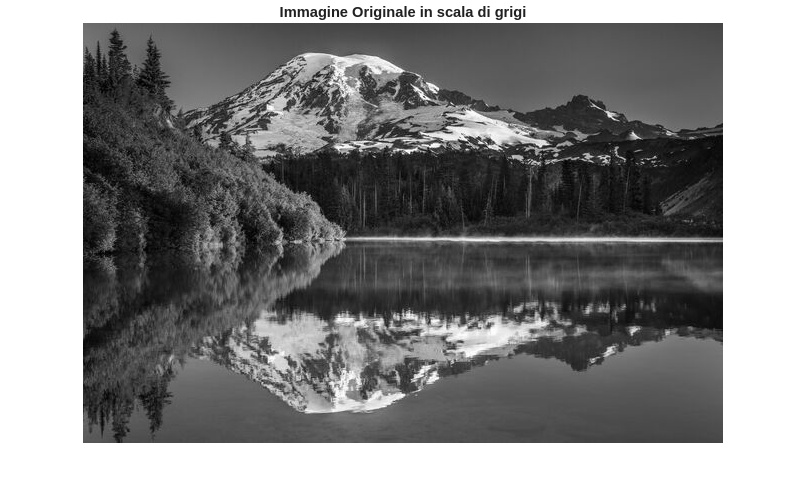

figure;
imshow(uint8(I_gray));
title('Original grayscale image');

#### SVD decomposition   

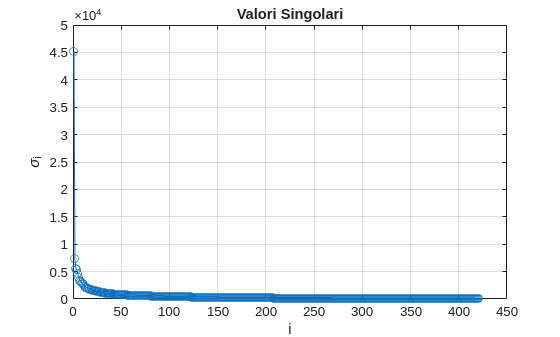

[U, S, V] = svd(I, 'econ');
singvals = diag(S);

figure;
plot(singvals, 'o-');
title('Singular values');
xlabel('i');
ylabel('\sigma_i');
grid on;

#### Compressione 

sigma_max = singvals(1);
soglia = 0.01*sigma_max;

% Cerchiamo l'indice dell'ultimo valore singolare che rispetta la
% condizione sigma_i >= 0.01*sigma_max
r = find(singvals >= soglia, 1, 'last')

r = 98

% Ricostruiamo l'immagine usando solo le prime r componenti
U_r = U(:,1:r);
S_r = S(1:r,1:r);
V_r = V(:,1:r);


#### Ricostruzione Immagine Compressa

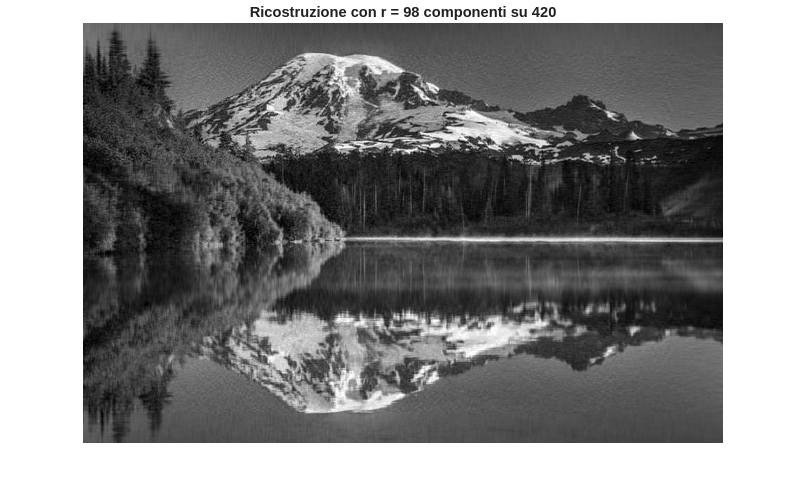

I_compressa = U_r*S_r*V_r';

figure;
imshow(uint8(I_compressa));
title(sprintf('Ricostruzione con r = %d componenti su %d', r, length(singvals)));

imshow(uint8(I_gray));
title('Immagine Originale in scala di grigi');

#### Errore Relativo

err = norm(I - I_compressa, 'fro') / norm(I, 'fro');
fprintf('Errore relativo (Frobenius) = %.4f\n', err);

Errore relativo (Frobenius) = 0.0708
